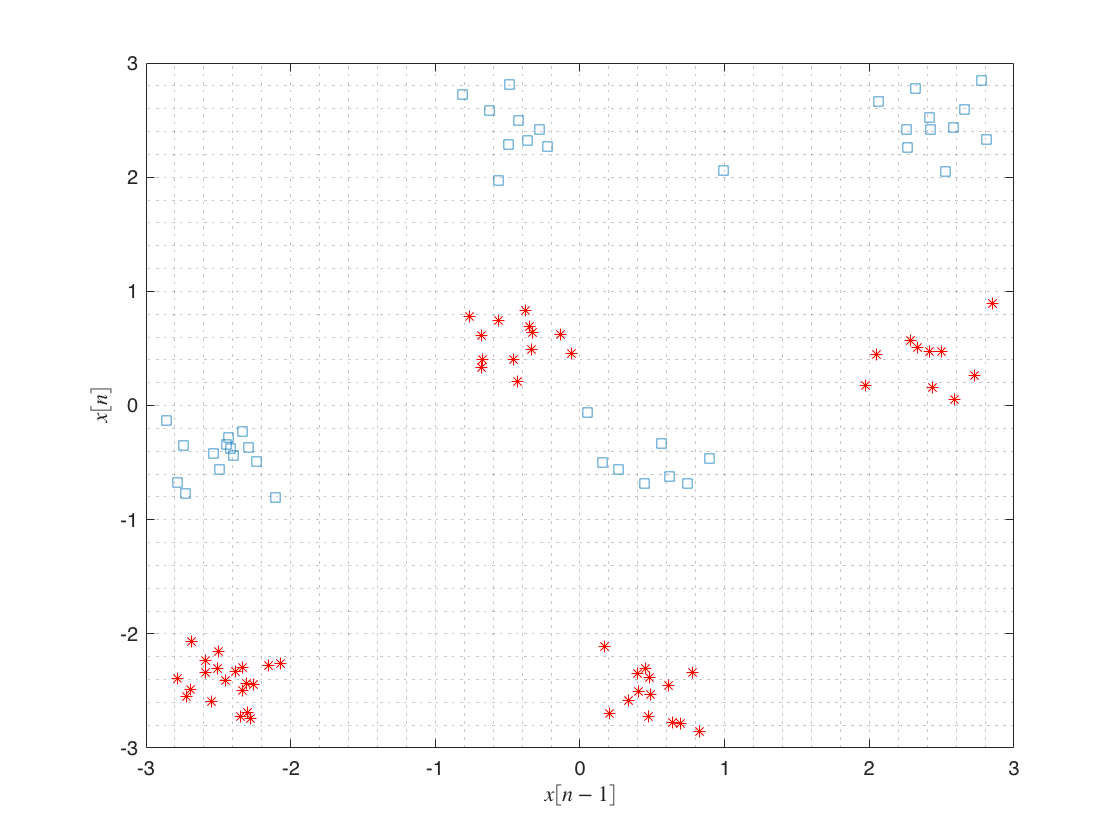

clear all;
close all;

    % Generating Random Numbers with a Seed 
    randn('seed',54432) 
    y = sign(randn(1,101));
    a = 1.5;
    x = filter([1 a],1,y) + 0.2 * randn(size(y));
    Y = y(2:end);

    X = buffer(x,2,1,'nodelay'); 
    i1 = find(y(2:end)==1);
    i2 = find(y(2:end)==-1);

figure(1)
plot(X(1,i1),X(2,i1),'s')
hold on
plot(X(1,i2),X(2,i2),'r*')
grid minor
xlabel('$x[n-1]$','Interpreter','latex')
ylabel('$x[n]$','Interpreter','latex')

% Mapping into kernel
[G1,G2] = meshgrid(linspace(-3,3,100), linspace(-3,3,100));

% Training the model
x_1 = X(1,:);

% Testing the model
x_1 = G1(:)';
y_1 = G2(:)';
x_3 = [x_1' y_1']';

% % Linear kernel function (provided in module)
% K_Exp_1 = kernelmatrix('lin',X,X,1);
% 
% % Nonlinear SVM Classfier
% SVM = svmtrain(Y',[(1:length(Y))',K_Exp_1], '-s 0 -t 4 -c 100 -h 0')
% idx = SVM.sv_indices';
% coff = SVM.sv_coef';
%  
% Alpha = zeros(1,100);
% j = 0;
% for i = 1:51
%     j = idx(i);
%     Alpha(j) = coff(i);
%     j+1;
% end
% 
% y = Alpha * K_Exp_1;
% 
% %% Dot products between data for test sets 
% 
% % Matrix RBF function
% K_Exp_2 = kernelmatrix('lin',X,x_3,1);
% Y_1 = Alpha * K_Exp_2;
% 
% % Reshape array dimesions
% R = reshape(Y_1,size(G1));
%  
% % Contour plot for matrix
% contour(G1,G2,R,[0 0],'LineWidth',1)

% % Poly kernel function (provided in module)
% K_Exp_1 = kernelmatrix('poly',X,X,1);
% 
% % Nonlinear SVM Classfier
% SVM = svmtrain(Y',[(1:length(Y))',K_Exp_1], '-s 0 -t 4 -c 100 -h 0')
% idx = SVM.sv_indices';
% coff = SVM.sv_coef';
%  
% Alpha = zeros(1,100);
% j = 0;
% for i = 1:51
%     j = idx(i);
%     Alpha(j) = coff(i);
%     j+1;
% end
% 
% y = Alpha * K_Exp_1;
% 
% %% Dot products between data for test sets 
% 
% % Matrix RBF function
% K_Exp_2 = kernelmatrix('poly',X,x_3,1);
% Y_1 = Alpha * K_Exp_2;
% 
% % Reshape array dimesions
% R = reshape(Y_1,size(G1));
%  
% % Contour plot for matrix
% contour(G1,G2,R,[0 0],'LineWidth',1)

% RBF kernel function (provided in module)
K_Exp_1 = kernelmatrix('rbf',X,X,1);

% Nonlinear SVM Classfier
SVM = svmtrain(Y',[(1:length(Y))',K_Exp_1], '-s 0 -t 4 -c 100 -h 0')

*
optimization finished, #iter = 55
nu = 0.003755
obj = -18.773564, rho = -0.031029
nSV = 15, nBSV = 0
Total nSV = 15


SVM = struct with fields:
    Parameters: [5×1 double]
      nr_class: 2
       totalSV: 15
           rho: -0.0310
         Label: [2×1 double]
    sv_indices: [15×1 double]
         ProbA: []
         ProbB: []
           nSV: [2×1 double]
       sv_coef: [15×1 double]
           SVs: [15×1 double]


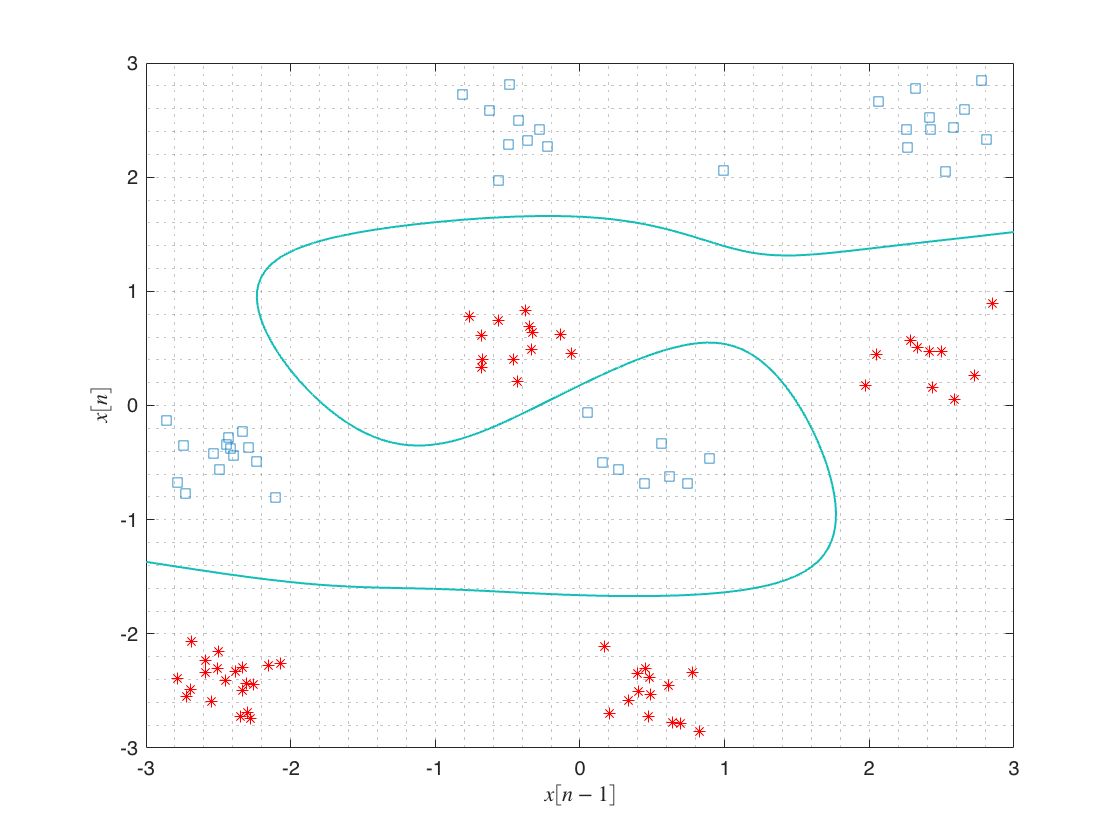

idx = SVM.sv_indices';
coff = SVM.sv_coef';
 
Alpha = zeros(1,100);
j = 0;
for i = 1:15
    j = idx(i);
    Alpha(j) = coff(i);
    j+1;
end

y = Alpha * K_Exp_1;

%% Dot products between data for test sets 

% Matrix RBF function
K_Exp_2 = kernelmatrix('rbf',X,x_3,1);
Y_1 = Alpha * K_Exp_2;

% Reshape array dimesions
R = reshape(Y_1,size(G1));
 
% Contour plot for matrix
contour(G1,G2,R,[0 0],'LineWidth',1)

function [X,y]=data(N,a)
N = N+1;
y = sign(randn(1,N));
x = filter([1 a],1,y)+0.2*randn(size(y));
X = buffer(x,2,1,'nodelay');  % Convolution
y = y(2:end);
end